Comparing the accuracy of pca for different values of k

The space contains all the photos reduced using pca. The reduced test image is compared to all the reduced train images and the best is taken.

Creating the train and test file

accuracy = zeros([15, 1]);
for k = 10:10:150
    load YaleB_32x32.mat
    %accuracy = 0;
    num_of_passes = 0;
    for iter=0:10    
        [data_size,image_size] = size(fea);
        image_size = sqrt(image_size);
        test_index = randi(data_size,1,100);
        train_index = 1:data_size;
        train_index(test_index) = [];
        
        train_face = fea(train_index,:)';
        train_label = gnd(train_index,:);
        test_face = fea(test_index,:)';
        test_label = gnd(test_index,:);
        train_size = size(train_index,2);
        test_size = size(test_index,2);

Mean

        train_mean = mean(train_face,2);
        train_face = train_face - train_mean;

Eigen-faces

        [eigen_faces,eigen_value,~] = svd(train_face'*train_face);
        eigen_faces = normc(train_face*eigen_faces);
        eigen_faces = eigen_faces(:,4:k+3); 
        eigen_value = diag(eigen_value);
        eigen_value = eigen_value(4:k+3)';

Projection

        train_weights = eigen_faces' * train_face;

Test

        test_weights = eigen_faces'*(test_face - train_mean);
        test_reduce = eigen_faces*test_weights;
        acc = test_size;
        for i = 1:test_size
            test = test_weights(:,i);
            no = vecnorm(train_weights - test);
            [M, I] = min(no);
            if train_label(I) ~= test_label(i)
                acc=acc-1;
            end
        end
        acc = acc*100/test_size;
        num_of_passes = num_of_passes+1;
        accuracy(k/10) = accuracy(k/10)+(acc-accuracy(k/10))/num_of_passes;
    end
    disp([k , accuracy(k/10)]);
end

   10.0000   51.0909

   20.0000   69.6364

   30.0000   76.9091

   40.0000   78.8182

    50    81

   60.0000   82.4545

   70.0000   83.5455

   80.0000   85.2727

   90.0000   85.3636

  100.0000   85.8182

  110.0000   83.7273

  120.0000   86.0000

  130.0000   86.6364

  140.0000   87.8182

  150.0000   85.6364



Plotting the accuracy

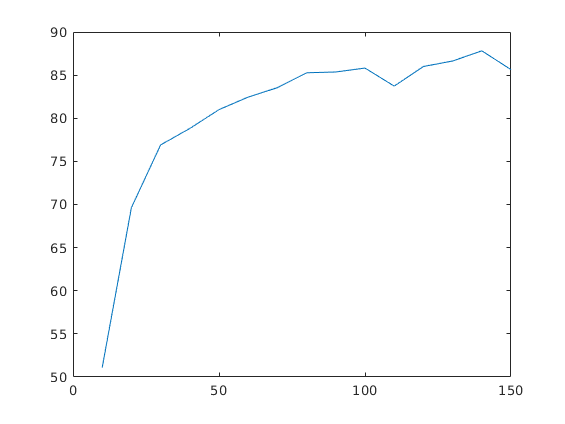

plot(10:10:150, accuracy)